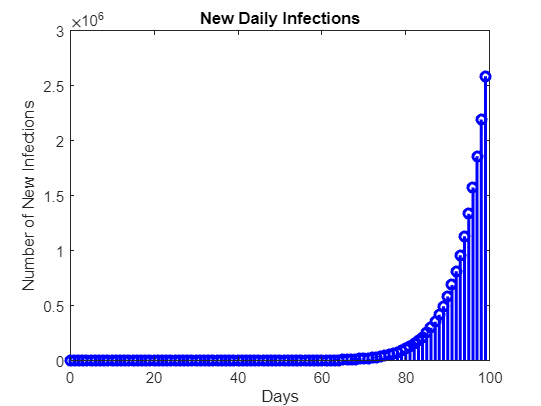

% Parameters
M = 12;
ak = [0.1, 0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1];
n_days = 100;

% Transfer function HM(z)
numerator = [1,0];
denominator = [1, -ak];
HM = tf(numerator, denominator);

% Kronecker delta input
input_signal = [1, zeros(1, n_days - 1)];

% Filtering
output_signal = filter(1, denominator, input_signal);

% Plot new daily infections
figure;
stem(0:n_days-1, output_signal, 'b', 'LineWidth', 2);
title('New Daily Infections');
xlabel('Days');
ylabel('Number of New Infections');

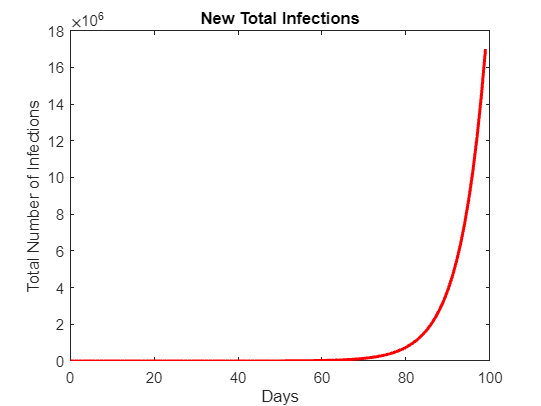


% Integrator filter
total_infections = cumsum(output_signal);

% Plot total infections
figure;
plot(0:n_days-1, total_infections, 'r', 'LineWidth', 2);
title('New Total Infections');
xlabel('Days');
ylabel('Total Number of Infections');


% Days to reach 1 million new daily infections
days_to_reach_million = find(total_infections >= 1e6, 1);
fprintf('Days to reach 1 million new daily infections: %d days\n', days_to_reach_million);

Days to reach 1 million new daily infections: 83 days
